## * CALISTA MAIN SCRIPT *

### Running CALISTA without time or cell stage information

Example 5. Hematopoietic stem cell differentiation (`Example_5_MOIGNARD_scRT_qPCR_NO_TIME_INFO.m` script in the main folder of CALISTA)

Analysis of RT-qPCR data in Moignard et al., [Characterization of transcriptional networks in blood stem and progenitor cells using high-throughput single-cell gene expression analysis, Nat. Cell Biol. 15, 363–72 (2013)](https://www.nature.com/articles/ncb2709).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
 curr_path='C:\Users\npgao\polybox\CALISTA-MATLAB_1.2.2';
% In MacOS
%curr_path='/Users/nan/polybox/CALISTA-MATLAB_1.2.2';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Moignard dataset (available in the subfolder *EXAMPLES/MOIGNARD*).

%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=1; % Single-cell RT-qPCR CT data
INPUTS.format_data=3; % Rows= cells and Columns= genes (no time info)
%
% Specify landscape plotting settings
INPUTS.ngrid=40; % Grid size for 2D interpolation
%
% Specify path analysis settings
INPUTS.plot_fig=1; % Plot figure of smoothened gene expression along path
INPUTS.hclustering=1; % Perform hierarchical clustering of gene expression for each path 
INPUTS.method=2; % Use pairwise correlation for the gene co-expression network (value_cutoff=0.8, pvalue_cutoff=0.01)
INPUTS.path_auto=0; % Manually define paths for further analysis

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  0.00

Selecting most variable genes...

Normalizing the data...

Finishing setup of the CALISTA data structure...

DONE.


## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

Following the original publication, we set the number of clusters equals to **5** in the command window:


CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Performing clustering based on consensus matrix...

Constructing consensus matrix...

Kmedois...
Elapsed time is 2.293008 seconds.

No time info found. Please enter the starting cell or the marker gene whenever available

Plotting...


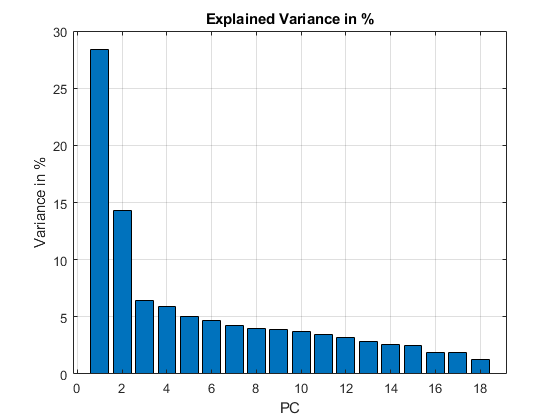

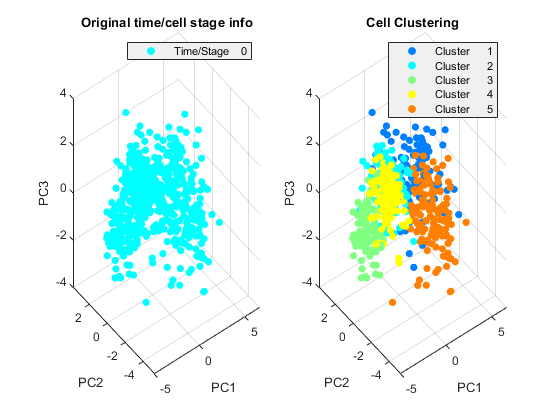

Elapsed time is 36.693662 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

If desired, users can remove cells from specific clusters from further analysis. In this example, we do not want to remove any clusters. Hence, we enter 0 (no cluster removal) and then 1 to proceed with lineage inference:

%  Cluster removal (if desired)
cluster_cut=input('Press 1 if you want to remove cell cluster(s). Press 0 otherwise: ');

if cluster_cut==1
    
   which_cut=input('Enter cluster index for removal (e.g 1 or [5 3]): ');
   cells_2_cut2=find(ismember(Results.final_groups,which_cut)==1);
   cells_2_cut2=DATA.cut_sort.abs_indices(cells_2_cut2);
   csvwrite('Cells_2_remove',cells_2_cut2)   
   RESULTS.cluster_cut = 1;
   fprintf('Cell''s indices to remove are saved in "Cells_2_remove.csv". Please run MAIN script again \n')
   return
end

Proceed=input(' Press 1 if you want to perform additional analysis (e.g. lineage inference, cell ordering) , 0 otherwise: ');
if ~Proceed
    return
end

## * 3-RECONSTRUCTION OF LINEAGE PROGRESSION *

Type '`help CALISTA_transition_main`' in the command window for more information. 

We follow the steps as outlined in the other examples to infer the lineage progression and carry out pseudotemporal ordering of single cells.

Without the time or cell stage info, CALISTA is still able to recover the cluster progression based on:

- The specification of the starting cell (e.g. cell 1);

- The specification of a marker gene (e.g. ‘Erg’) which is downregulated (press 2):

- The specification of the starting cluser (e.g. cluster 4);


CALISTA_transition is running...



4 edge(s) have been added and the graph is connected. 
If you want to add another edge press "p" 
If you want to remove an edge press "m" 
If you want to continue with the next step press "enter" 
(Please make sure that figure 101 is in the foreground and no additional tools are selected (e.g. zooming, rotation, data cursor etc.)) 

----------------------------------------------



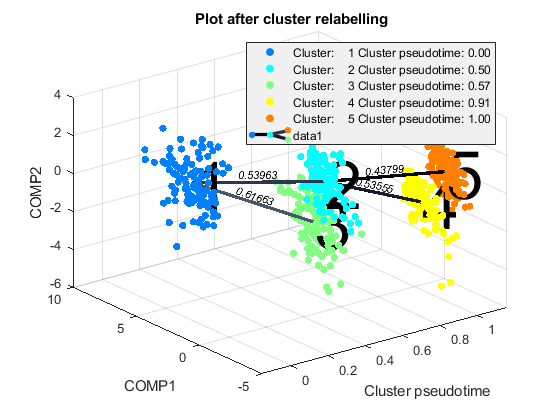

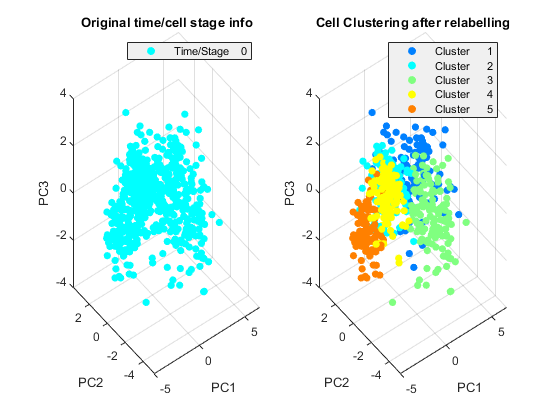

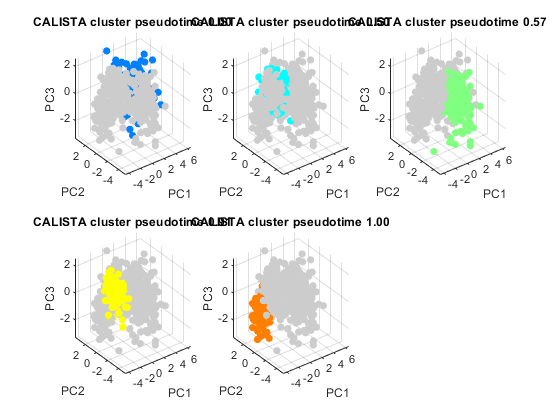


Plotting mean gene expressions...


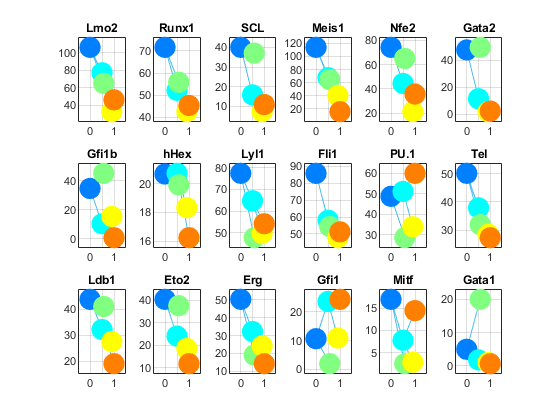


DONE.


[Results]=CALISTA_transition_main(DATA,INPUTS,Results);

% % Save 3D video
% figure(100)
% % daspect([2,2,0.3]);
% OptionZ.FrameRate=20;OptionZ.Duration=20.5;OptionZ.Periodic=true;
% CaptureFigVid([-20,10;-110,10;-190,80;-290,10;-380,10], 'CALISTA_lineage_3Dvideo',OptionZ)

Without any information of the time information, cell stage, starting cell and marker genes, CALISTA is still able to find the topology of the lineage graph, but the edges are undirected.

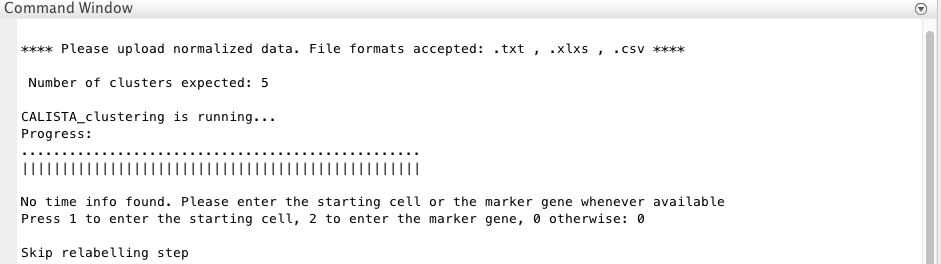

CALISTA single-cell clustering result is as follows.

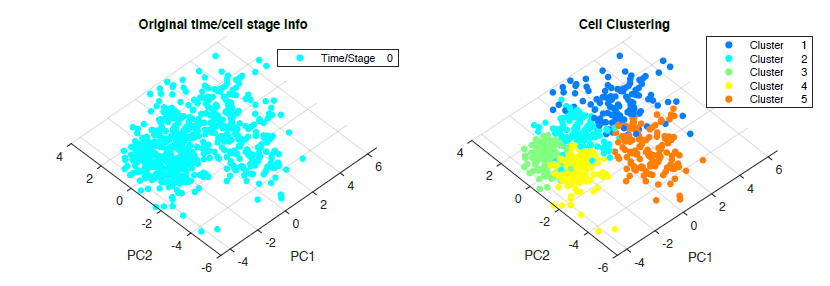

The final inferred lineage relationships are shown below.

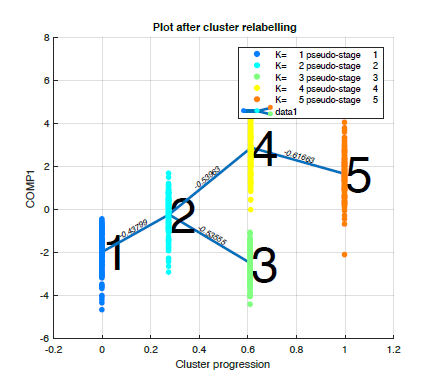

Therefore, CALISTA performs the pseudotemporal ordering of cells as follows: